%{
Program to denoise images using low rank completion methods
Harsh Shah and Pranava Singhal 
%}

addpath '.\MMread';
rng(73);

[video, audio] = mmread('.\data\akiyo_cif.y4m');

% reading the meta data and frames of the video 
H = video.height;
W = video.width;
K = 50;
num_channels = 3;
frames = zeros(H, W, num_channels, K);
for i=1:1:K
    frames(:, :, :, i) = uint8(video.frames(i).cdata);
end
frames = uint8(frames);

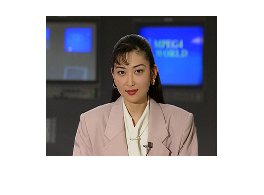

imshow(frames(:, :, :, 1))

% noise generation
sigma = 20; 
kappa = 5;
mu = 0;
s = 0.3;
groundTruth = frames(:, :, :, 1);


noisy_video = zeros(H,W,num_channels,K);
for T = 1:K
    noisy_video(:,:,:,T) = noisify(frames(:,:,:,T), sigma, mu, kappa, s);
end

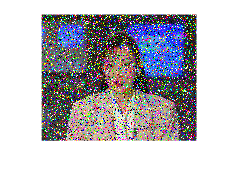

imshow(noisy_video(:,:,:,10))

% denoising using adaptive median filtering
num_testing_frames = K;
tic
 [omega , denoised_frames] = ramf_optimized1(noisy_video(:,:,:,1:num_testing_frames));
timeElapsed = toc

timeElapsed = 69.0121

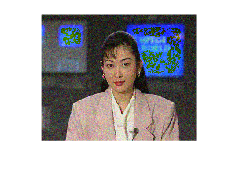

imshow(denoised_frames(:,:,:,1));

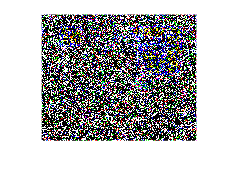

imshow(omega(:,:,:,1));

patch_dim = 8;
stride = 4;
final_denoised_images = zeros(H, W, num_channels, num_testing_frames);
ref_patches = generatePatches_overlapping(denoised_frames(:,:,1,1), patch_dim, stride);


% TODO : find sigma for mu
num_frames_to_denoise = 1;
reconstructed_images = zeros(H, W, num_channels, K);
x_patches = (W+stride-patch_dim)/stride;
y_patches = (H+stride-patch_dim)/stride;
for f=1:num_frames_to_denoise
    for c=1:num_channels
        ref_patches = generatePatches_overlapping(denoised_frames(:,:,c,f), patch_dim, stride);
        denoised_patches = zeros(size(ref_patches));
        
        for i=1:size(ref_patches, 4)
            tic
            [matchingPatches, indices] = patchMatch(ref_patches(:,:,:,i),denoised_frames(:,:,c,1:K),5);
            elapsed_time1 = toc
            tic
            [omega_1, Pjk] = concatMatching(1, 50, matchingPatches, indices, omega);
            elapsed_time2 = toc
            tic
            [omega_2, sigma_cap]= outliers_removal(Pjk, omega_1);
            elapsed_time3 = toc
            omega_2 = not(omega_2);
            p = sum(omega_2, 'all')/(size(Pjk, 1)*size(Pjk, 2));
            mu = (sqrt(size(Pjk, 1)) + sqrt(size(Pjk, 1)))*sqrt(patch_dim)*sigma_cap;
            %A_mat = mask_to_matrix(omega_2);
            tic
            filled_patch = fixed_point_minimization(omega_2, Pjk, mu, -1, -1, -1);
            denoised_patches(:, :, 1, i) = filled_patch;
            elapsed_time4 = toc
            break
        end
        break
        reconstructed_images(:, :, c, f) = imageReconstruction_overlapping(denoised_patches, x_patches, y_patches, stride);
    end
    break
end

elapsed_time1 = 0.3066

elapsed_time2 = 0.0222

elapsed_time3 = 0.0033

elapsed_time4 = 0.2016

imshow(reconstructed_images(:, :, :, 1));


% 

% outliers removal (omega generation stage 2)
test = randn(3,3)
a = outliers_removal(test, ones(3,3));

%  


% patch generation
patch_dim = 8;
stride = 4;
patches = generatePatches_overlapping(denoised_frames(:,:,:,1), patch_dim, stride);

% mask to matrix testing
A = (rand(8)<0.5)
B = mask_to_matrix(A);

function for adding noise to a given image

groundTruth: uint8 

function result = noisify(groundTruth, sigma, mu, kappa, s)
    H = size(groundTruth, 1);
    W = size(groundTruth, 2);
    num_channels = size(groundTruth, 3);
    gaussian_noise = normrnd(mu, sigma, H, W, num_channels);
    poisson_noise = poissrnd(kappa, H, W, num_channels);
    
    result = double(groundTruth) + gaussian_noise + poisson_noise;
    
    result(result > 255) = 255;
    result(result < 0) = 0;

    for i=1:H
        for j=1:W
            if rand() < s
                result(i, j, :) = noisy_pixel(num_channels);
            end
        end
    end
    result = result/255;
end

% functin for generating salt and pepper noise
function pixel = noisy_pixel(num_channels)
    pixel = zeros(1, 1, 3);
    for i=1:num_channels
        if rand() < 0.5
            pixel(1, 1, i) = 0;
        else
            pixel(1, 1, i) = 255;
        end
    end
end

% function for soft shrinkage 
function result = soft_shrinkage(A, tau)
    [U, S, V] = svd(A);
    S(S>0) = S(S>0)-tau;
    S(S<0) = 0;
    result = U*S*V';
end

function patches = generatePatches_nonoverlap(image, patch_r, patch_c) 
    rows = size(image, 1);
    columns = size(image, 2);
    wholeBlockRows = floor(rows / patch_r);
    wholeBlockCols = floor(columns / patch_c);
    trailing_rows = rows - wholeBlockRows * patch_r;
    trailing_cols = columns - wholeBlockCols * patch_c;
    image3d_cell = mat2cell( image, [ patch_r * ones(1, wholeBlockRows), trailing_rows], [patch_c * ones(1, wholeBlockCols), trailing_cols], size(image, 3) );
    if trailing_rows == 0 && trailing_cols == 0
      patches = cat( ndims(image)+1, image3d_cell{1:end-1,1:end-1} );
    else
      display("Image size and patch size not compatible");    
    end
end

% function to generate overlapping patches
function patches = generatePatches_overlapping(image, patch_dim, stride)
    height = size(image, 1);
    width = size(image, 2);
    T = size(image, 3);
    assert(rem(height-patch_dim, stride) == 0);
    assert(rem(width-patch_dim, stride) == 0);
    blocks_x = (width-patch_dim)/stride+1;
    blocks_y = (height-patch_dim)/stride+1;
    
    patches = zeros(patch_dim, patch_dim, T, blocks_x*blocks_y);

    for i=1:blocks_x
        for j=1:blocks_y
            patch = image((j-1)*stride+1 : patch_dim+(j-1)*stride,(i-1)*stride+1 : patch_dim+(i-1)*stride, :);
            patches(:, :, :, (i-1)*blocks_y+j) = patch;
        end
    end
end

% for stiching the non-overlapping patches
function result = imageReconstruction_non_overlapping(all_patches, x_patches, y_patches)
    all_patches_size = size(all_patches);
    num_patches = all_patches_size(1);
    patch_size = all_patches_size(2);
    T = all_patches_size(4);
    assert(num_patches*patch_size*patch_size*T == y_patches*patch_size*x_patches*patch_size*T);
    reconstruction = zeros(y_patches*patch_size, x_patches*patch_size, T);
    for i = 1:x_patches
        for j = 1:y_patches
            reconstruction((j-1)*patch_size+1:j*patch_size, (i-1)*patch_size+1:i*patch_size, :) = all_patches((i-1)*y_patches + j, :, :, :);
        end
    end
    result = reconstruction;
end

% function to stitch image from overlapping patches
function result = imageReconstruction_overlapping(all_patches, x_patches, y_patches, stride)
    all_patches_size = size(all_patches);
    patch_dim = all_patches_size(2);
    T = all_patches_size(4);
    height = patch_dim + stride*(y_patches-1);
    width = patch_dim + stride*(x_patches-1);
    
    reconstruction = zeros(height, width, T);
    count_mat = zeros(height, width, T);
    for i = 1:x_patches
        for j = 1:y_patches
            reconstruction((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) = reconstruction((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) + squeeze(all_patches((i-1)*y_patches + j, :, :, :));
            count_mat((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) = count_mat((j-1)*stride+1:(j-1)*stride+patch_dim, (i-1)*stride+1:(i-1)*stride+patch_dim, :) + ones(patch_dim, patch_dim, T);
        end
    end
    result = reconstruction./count_mat;  
end


function [omega, denoised_frames] = ramf(frames)
    H = size(frames, 1);
    W = size(frames, 2);
    num_channels = size(frames, 3);
    K = size(frames, 4);
    denoised_frames = double(zeros(size(frames)));
    omega = zeros(size(frames));
    for T = 1:K
        for i = 1:H
            for j = 1:W
                % stage 1 filtering
                for window_size = 3:2:floor(min(H/2,W/2))
                    delta = floor((window_size-1)/2);
                    pixels_in_window = zeros(window_size, window_size, num_channels);
                    for r = (i-delta):(i+delta)
                        for s = (j-delta):(j+delta)
                            if((r>= 1) && (s>=1) && (r<=H) && (s<= W))
                                pixels_in_window(r-i+delta+1,s-j+delta+1, :) = frames(r,s,:,T);
                            else
                                % locations outside frame
                                pixels_in_window(r-i+delta+1,s-j+delta+1, :) = -1;
                            end
                        end
                    end
                    
                    x_median = zeros([1,1,num_channels]);
                    x_min = zeros([1,1,num_channels]);
                    x_max = zeros([1,1,num_channels]);
                    
                    for channel = 1:num_channels
                        pixels_in_channel = pixels_in_window(:,:,channel);
                        valid_pixels = pixels_in_channel(pixels_in_channel >= 0);
                        x_median(:,:,channel) = median(valid_pixels(:));
                        x_min(:,:,channel) = min(valid_pixels(:));
                        x_max(:,:,channel) = max(valid_pixels(:));
                    end 
                    
                    T_minus = x_median - x_min;
                    T_plus = x_median - x_max;
                    if(sum(T_minus>0 & T_plus<0) == num_channels)
                        % stage 2 filtering
                        x_ij = frames(i,j,:,T);
                        %x_ij_squeeze = reshape(x_ij,[1,3]);
                                            
                        U_minus = x_ij - x_min;
                        U_plus = x_ij - x_max;

                        if(sum(U_minus>0 & U_plus<0) == num_channels)
                            denoised_frames(i,j,:,T) = x_ij;
                        else
                            denoised_frames(i,j,:,T) = x_median;
                            omega(i,j,:,T) = 1;
                        end
                        break;
                    end   
                end
            end
        end
    end  
end

function [omega, denoised_frames] = ramf_optimized(frames)
    H = size(frames, 1);
    W = size(frames, 2);
    num_channels = size(frames, 3);
    K = size(frames, 4);
    denoised_frames = double(zeros(size(frames)));
    omega = zeros(size(frames));
    max_window = 15;
    for T = 1:K
        logical_arr_stage1_prev = zeros(H, W);
        for window_size = 3:2:max_window
            logical_arr_stage1_channels = zeros(H,W,num_channels);
            logical_arr_stage1 = ones(H,W);
            for c=1:num_channels
                %delta = floor((window_size-1)/2);
                %padded_frame = padarray(frames(:,:,c,T),[delta delta],'replicate','both');
                padded_frame = frames(:,:,c,T);
                max_frame = ordfilt2(padded_frame, window_size*window_size, ones(window_size,window_size),'symmetric');
                min_frame = ordfilt2(padded_frame, 1, ones(window_size,window_size), 'symmetric');
                median_frame = ordfilt2(padded_frame, (window_size*window_size+1)/2, ones(window_size,window_size), 'symmetric');
                % display(size(min_frame))
                % display(size(median_frame))
                logical_arr_stage1_channels(:,:,c) = ((median_frame-min_frame)>0) & ((median_frame-max_frame)<0) & not(logical_arr_stage1_prev);
                logical_arr_stage1 = logical_arr_stage1_channels(:, :, c) & logical_arr_stage1;
 
            end
 
            logical_arr_stage2_corrupted_channels = zeros(H,W,num_channels);
            logical_arr_stage2_corrupted = ones(H,W);
            logical_arr_stage2_uncorrupted_channels = zeros(H,W,num_channels);
            logical_arr_stage2_uncorrupted = ones(H,W);
            for c = 1:num_channels
                padded_frame = frames(:,:,c,T);
                max_frame = ordfilt2(padded_frame, window_size*window_size, ones(window_size,window_size),'symmetric');
                min_frame = ordfilt2(padded_frame, 1, ones(window_size,window_size), 'symmetric');
                logical_arr_stage2_uncorrupted_channels(:,:,c) = ((frames(:,:,c,T)-min_frame)>0) & ((frames(:,:,c,T)-max_frame)<0) & logical_arr_stage1;
                logical_arr_stage2_corrupted_channels(:,:,c) = not(((frames(:,:,c,T)-min_frame)>0) & ((frames(:,:,c,T)-max_frame)<0)) & logical_arr_stage1;
                logical_arr_stage2_corrupted = logical_arr_stage2_corrupted & logical_arr_stage2_corrupted_channels(:, :, c);
                logical_arr_stage2_uncorrupted = logical_arr_stage2_uncorrupted & logical_arr_stage2_uncorrupted_channels(:, :, c);
            end
 
            for c = 1:num_channels
                denoised_frame_to_change = denoised_frames(:, :, c, T);
                denoised_frame_to_change(logical_arr_stage2_corrupted==1) = 0;
                padded_frame = frames(:,:,c,T);
                median_frame = ordfilt2(padded_frame, (window_size*window_size+1)/2, ones(window_size,window_size), 'symmetric');
                denoised_frame_to_change = denoised_frame_to_change + median_frame.*logical_arr_stage2_corrupted;
 
                denoised_frame_to_change(logical_arr_stage2_uncorrupted) = 0;
 
                denoised_frame_to_change = denoised_frame_to_change + frames(:, :, c, T).*logical_arr_stage2_uncorrupted;
                denoised_frames(:, :, c, T) = denoised_frame_to_change;
            end
 
            % display(size(denoised_frames))
            for c=1:num_channels
                omega_temp = omega(:, :, c, T);
                omega_temp(logical_arr_stage2_corrupted) = 1;
                omega(:, :, c, T) = omega_temp;
            end
            logical_arr_stage1_prev = logical_arr_stage1 | logical_arr_stage1_prev; 
            if (sum(logical_arr_stage1_prev,'all')==H*W)
                break;
            end
        end
    end
end  


function [omega, denoised_frames] = ramf_optimized1(frames)
    H = size(frames, 1);
    W = size(frames, 2);
    num_channels = size(frames, 3);
    K = size(frames, 4);
    denoised_frames = double(zeros(size(frames)));
    omega = zeros(size(frames));
    max_window = 15;
    for T = 1:K
        for c=1:num_channels
            logical_arr_stage1_prev = zeros(H, W);
            for window_size = 3:2:max_window
                delta = floor((window_size-1)/2);
                %padded_frame = padarray(frames(:,:,c,T),[delta delta],'replicate','both');
                padded_frame = frames(:,:,c,T);
                max_frame = ordfilt2(padded_frame, window_size*window_size, ones(window_size,window_size),'symmetric');
                min_frame = ordfilt2(padded_frame, 1, ones(window_size,window_size), 'symmetric');
                median_frame = ordfilt2(padded_frame, (window_size*window_size+1)/2, ones(window_size,window_size), 'symmetric');
                % display(size(min_frame))
                % display(size(median_frame))
       
                logical_arr_stage1 = ((median_frame-min_frame)>0) & ((median_frame-max_frame)<0) & not(logical_arr_stage1_prev);
                
                logical_arr_stage2_uncorrupted = ((frames(:,:,c,T)-min_frame)>0) & ((frames(:,:,c,T)-max_frame)<0) & logical_arr_stage1;
                logical_arr_stage2_corrupted = not(((frames(:,:,c,T)-min_frame)>0) & ((frames(:,:,c,T)-max_frame)<0)) & logical_arr_stage1;
                denoised_frame_to_change = denoised_frames(:, :, c, T);
                denoised_frame_to_change(logical_arr_stage2_corrupted==1) = 0;
                
                % display(size(denoised_frames))

                denoised_frame_to_change = denoised_frame_to_change + median_frame.*logical_arr_stage2_corrupted;
                
                denoised_frame_to_change(logical_arr_stage2_uncorrupted) = 0;
     
                denoised_frame_to_change = denoised_frame_to_change + frames(:, :, c, T).*logical_arr_stage2_uncorrupted;
                
                denoised_frames(:, :, c, T) = denoised_frame_to_change;
                omega_temp = omega(:, :, c, T);
                omega_temp(logical_arr_stage2_corrupted) = 1;
                omega(:, :, c, T) = omega_temp;
                logical_arr_stage1_prev = logical_arr_stage1 | logical_arr_stage1_prev; 
            end
        end
    end  
end



function result = mask_to_matrix(mask)
    H = size(mask, 1);
    W = size(mask, 2);
    num_ones = sum(mask, 'all');
    result = zeros(num_ones, H*W);
    curr_row = 1;
    for i = 1:H
        for j = 1:W
            if mask(i, j) == 1
                result(curr_row, (i-1)*W + j) = 1;
                curr_row = curr_row + 1;
            end
        end
    end
end


% algorithm for rank miniization problem
function result = fixed_point_minimization(P, GT, mu, tau, max_iterations, threshold)
    n1 = size(P, 1);
    n2 = size(P, 2);
    if max_iterations == -1
        max_iterations = 100;
    end
    if tau == -1
        tau = 1.5;
    end
    if threshold == -1
        threshold = 0.0001;
    end

    curr_iter = 0;
    Q_new = zeros(n1, n2);
    Q_prev = zeros(n1, n2);
    R = zeros(n1, n2);
    converged = false;
    convergence_num = 5; 
    curr_conv = 0;
    while curr_iter < max_iterations && not(converged)
        R = Q_prev - tau*(P.*(Q_prev - GT));
        Q_new = soft_shrinkage(R, tau*mu);
        if norm(Q_prev - Q_new, "fro") < threshold && norm(P.*(Q_prev - GT), "fro") < threshold
            curr_conv = curr_conv + 1;
        end
        if curr_conv == convergence_num
            converged = true;
        end
        curr_iter = curr_iter + 1;
        Q_prev = Q_new;
    end
    result = reshape(Q_new(:,1), sqrt(n1), sqrt(n1));
end


% removing outliers from omega
function [result, sigma_cap] = outliers_removal(patch_mat, omega)
    H = size(patch_mat, 1);
    W = size(patch_mat, 2);
    std_vec = sqrt(var(patch_mat,0, 2));
    mean_vec = mean(patch_mat, 2);
    result = omega;
    for i=1:H
        for j=1:W
            if abs(mean_vec(i, 1) - patch_mat(i,j)) >= 2*std_vec(i, 1)
                result(i, j) = 1;
            end
        end
    end
    sigma_cap = mean(std_vec, 'all');
end

% function to concatenate patches to generate the require
% low rank matrices
function [omega_1, Pjk] = concatMatching(frame_index, K, matchingPatches, indices, omega_video)
    Kxmatches = size(matchingPatches, 1);
    matches = floor(Kxmatches/K);
    ref_patch = matchingPatches(matches*(frame_index-1)+1,:,:,:);
    ref_patch_index = indices(matches*(frame_index-1)+1,:);
    matchingPatches(matches*(frame_index-1)+1,:,:,:) = matchingPatches(1,:,:,:);
    indices(matches*(frame_index-1)+1,:) = indices(1,:);
    matchingPatches(1,:,:,:) = ref_patch;
    indices(1,:) = ref_patch_index;
    patch_size = size(ref_patch,2);
    omega_patches = zeros(size(matchingPatches));
    Pjk = zeros(patch_size*patch_size, Kxmatches);
    omega_1 = zeros(patch_size*patch_size, Kxmatches);
    for c = 1:Kxmatches
        idx_i = indices(c,1);
        idx_j = indices(c,2);
        idx_T = indices(c,3);
        omega_patches(c,:,:,:) = omega_video(idx_i:idx_i+patch_size-1,idx_j:idx_j+patch_size-1,1,idx_T);
        Pjk(:,c) = reshape(matchingPatches(c,:,:,1),[patch_size*patch_size,1]);
        omega_1(:,c)  = reshape(omega_patches(c,:,:,1),[patch_size*patch_size,1]);
    end
end

% function to generate matching patches given a reference patch
function [matchingPatches, indices] = patchMatch(ref_patch, frames, matches_per_frame)
    num_channels = size(frames, 3);
    K = size(frames, 4);
    patch_size = size(ref_patch, 1);
    matchingPatches = zeros(K*matches_per_frame, patch_size, patch_size, num_channels);
    indices = zeros(K*matches_per_frame, 3);
    for T = 1:K
        [matchingPatches((T-1)*matches_per_frame+1:T*matches_per_frame,:,:,:),indices((T-1)*matches_per_frame+1:T*matches_per_frame,1:2)] = patchMatchPerFrame_optimized(ref_patch, frames(:,:,:,T), matches_per_frame);
        indices((T-1)*matches_per_frame+1:T*matches_per_frame,3) = T;
    end
end

% patching matching in a frame given the reference patch
function [matchingPatches, indices] = patchMatchPerFrame(ref_patch,frame,num_matches)
    H = size(frame, 1);
    W = size(frame, 2);
    num_channels = size(frame, 3);
    patch_size = size(ref_patch,1);
    MAD_array = zeros(H-patch_size+1, W-patch_size+1);
    for i = 1:H-patch_size+1
        for j = 1:W-patch_size+1
            patch_ij = frame(i:i+patch_size-1,j:j+patch_size-1,:);
            if ((rem(i,2)==1)&&(rem(j,2)==1))
                pattern = 'a';
            elseif ((rem(i,2)==0)&&(rem(j,2)==1))
                pattern = 'b';
            elseif ((rem(i,2)==0)&&(rem(j,2)==0))
                pattern = 'c';
            elseif ((rem(i,2)==1)&&(rem(j,2)==0))
                pattern = 'd';
            end
            MAD_array(i,j) = MAD(ref_patch, patch_ij,pattern);
        end
    end
    [lx,~] = size(MAD_array);
    [~,minIndices] = mink(MAD_array(:), num_matches);
    indices = zeros(size(minIndices,1),2);
    matchingPatches = zeros(size(minIndices,1),patch_size, patch_size, num_channels);
    for c = 1:size(minIndices,1)
        idx = minIndices(c)-1;
        idx_j = floor(idx/lx);
        idx_i = idx - idx_j*lx;
        idx_i = idx_i + 1;
        idx_j = idx_j + 1;
        indices(c,:) = [idx_i,idx_j];
        matchingPatches(c,:,:,:) = frame(idx_i:idx_i+patch_size-1,idx_j:idx_j+patch_size-1,:);
    end    
end

% patching matching in a frame given the reference patch
function [matchingPatches, indices] = patchMatchPerFrame_optimized(ref_patch,frame,num_matches)
    H = size(frame, 1);
    W = size(frame, 2);
    num_channels = size(frame, 3);
    patch_size = size(ref_patch,1);
    x_rep = W/patch_size + 1;
    y_rep = H/patch_size + 1;
    ref_matrix = repmat(ref_patch, y_rep, x_rep);
    MAD_array = zeros(H-patch_size+1, W-patch_size+1);

    for i=1:patch_size
        repmat_mod = ref_matrix(i:H+i-1, i:W+i-1);
        diff_mat = abs(repmat_mod-frame);
        mean_mat = conv2(diff_mat, ones(patch_size)./(patch_size^2), 'valid');
        MAD_array(i:8:end, i:8:end) = mean_mat(i:8:end, i:8:end);
    end

    [lx,~] = size(MAD_array);
    [~,minIndices] = mink(MAD_array(:), num_matches);
    indices = zeros(size(minIndices,1),2);
    matchingPatches = zeros(size(minIndices,1),patch_size, patch_size, num_channels);
    for c = 1:size(minIndices,1)
        idx = minIndices(c)-1;
        idx_j = floor(idx/lx);
        idx_i = idx - idx_j*lx;
        idx_i = idx_i + 1;
        idx_j = idx_j + 1;
        indices(c,:) = [idx_i,idx_j];
        matchingPatches(c,:,:,:) = frame(idx_i:idx_i+patch_size-1,idx_j:idx_j+patch_size-1,:);
    end    
end

% function to return mean absolute difference 
% given the pattern to find it
function MeanAbsDiff = MAD(patch1, patch2, pattern)
    patch_size = size(patch1, 1);
    assert(size(patch2,1) == patch_size);
    MeanAbsDiff = 0;
    if pattern == 'a'
        patch1_extract = patch1(1:2:patch_size,1:2:patch_size,:);
        patch2_extract = patch2(1:2:patch_size,1:2:patch_size,:);
        size_a = size(patch1_extract,1);
        MeanAbsDiff = sum(abs(patch1_extract - patch2_extract),'all');
        MeanAbsDiff = MeanAbsDiff/(size_a*size_a);
    elseif pattern == 'b'
        patch1_extract = patch1(1:2:patch_size,2:2:patch_size,:);
        patch2_extract = patch2(1:2:patch_size,2:2:patch_size,:);
        size_b = size(patch1_extract,1);
        MeanAbsDiff = sum(abs(patch1_extract - patch2_extract),'all');
        MeanAbsDiff = MeanAbsDiff/(size_b*size_b);
    elseif pattern == 'c'
        patch1_extract = patch1(2:2:patch_size,1:2:patch_size,:);
        patch2_extract = patch2(2:2:patch_size,1:2:patch_size,:);
        size_c = size(patch1_extract,1);
        MeanAbsDiff = sum(abs(patch1_extract - patch2_extract),'all');
        MeanAbsDiff = MeanAbsDiff/(size_c*size_c);
    elseif pattern == 'd'
        patch1_extract = patch1(2:2:patch_size,2:2:patch_size,:);
        patch2_extract = patch2(2:2:patch_size,2:2:patch_size,:);
        size_d = size(patch1_extract,1);
        MeanAbsDiff = sum(abs(patch1_extract - patch2_extract),'all');
        MeanAbsDiff = MeanAbsDiff/(size_d*size_d);
    elseif pattern == 'all'
        MeanAbsDiff = sum(abs(patch1- patch2),'all');
        MeanAbsDiff = MeanAbsDiff/(patch_size*patch_size);
    end
end